# Práctico 1 - Representación de Sistemas y PID

## Caso de estudio N° 1: Sistema de dos variables de estado

1 - Asignar valores a R=4,7KOhm, L=10uHy, y C=100nF. Obtener simulaciones que permitan estudiar la dinámica del sistema, con una entrada de tensión escalón de 12V, que cada 1ms cambia de signo.

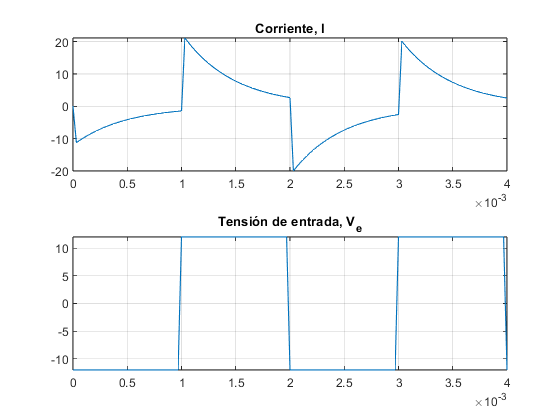

%Generamos señal de entrada:
%Onda cuadrada alterna de 2ms de periodo y 12V de amplitud
[u,t] = gensig("square",2e-03,4e-03);
u=24*u-12;
R=4.7e03; L=10e-06; C=100e-09; %Parámetros del circuito RLC
A1 = [-R/L -1/L; 1/C 0];
B1 = [1/L; 0];
C1 = [R 0];
D1 = [0];


% Creamos modelo de espacio de estados
sys = ss(A1,B1,C1,D1);

[i,t]=lsim(sys,u,t);

figure('Name','1.1')
 subplot(2,1,1);plot(t,i);grid on; title('Corriente, I'); 
 subplot(2,1,2);plot(t,u);grid on; title('Tensión de entrada, V_e');

2- Asignar valores a R=5,6KOhm, L=10uHy, y C=100nF; repetir lo anterior para comparar el resultado y verificar la correcta simulación.

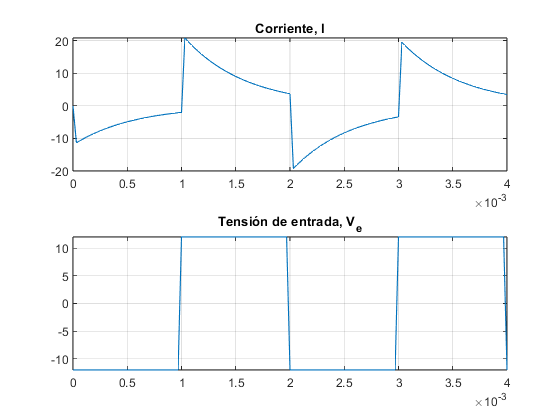

 % Modelamos de nuevo el mismo sistema, pero con valores de R diferentes
R = 5.6e03;

A2 = [-R/L -1/L; 1/C 0];
B2 = [1/L; 0];
C2 = [R 0];
D2 = [0];


% Creamos modelo de espacio de estados
sys = ss(A2,B2,C2,D2);

[i,t]=lsim(sys,u,t);

figure('Name', '1.2')
 subplot(2,1,1);plot(t,i);grid on; title('Corriente, I');
 subplot(2,1,2);plot(t,u);grid on; title('Tensión de entrada, V_e');

3- En el archivo Curvas_Medidas_RLC.xls (datos en la hoja 1 y etiquetas en la hoja 2) encontrarán las series de datos que deberían emplear para deducir los valores de R, L y C del circuito. Emplear el método de la respuesta al escalón, tomando como salida la tensión en el capacitor.

clear all;
%Cargamos los datos medidos
datos = xlsread('Curvas_Medidas_RLC.xls');

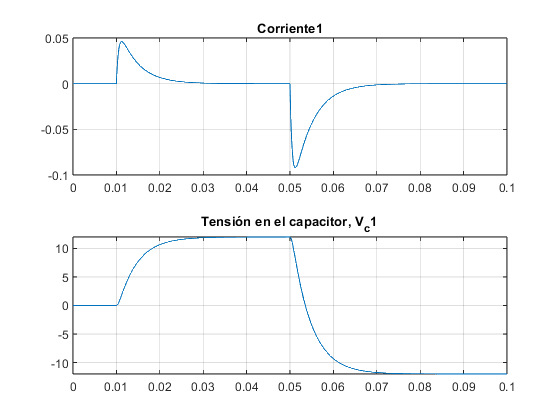

t = datos(:,1);
i = datos(:,2);
v_c = datos(:,3);

figure('Name', '1.2')
 subplot(2,1,1);plot(t,i);grid on; title('Corriente1');
 subplot(2,1,2);plot(t,v_c);grid on; title('Tensión en el capacitor, V_c1');

% Determinamos el modelo del circuito RLC a partir del método desarollado
% por Chen

td = 0.01;
t1 = 0.002;
k=max(v_c);
[val lugar] = min(abs((t1+td)-t))

val = 0

lugar = 121

k1 = v_c(lugar)/k-1

k1 = -0.7110

[val lugar] = min(abs((2*t1+td)-t))

val = 0

lugar = 141

k2 = v_c(lugar)/k-1

k2 = -0.4494

[val lugar] = min(abs((3*t1+td)-t))

val = 0

lugar = 161

k3 = v_c(lugar)/k-1

k3 = -0.2830

b=4*k1^3*k3-3*k1^2*k2^2-4*k2^3+k3^2+6*k1*k2*k3;
alfa1 = (k1*k2+k3-sqrt(b))/(2*(k1^2+k2));
alfa2 = (k1*k2+k3+sqrt(b))/(2*(k1^2+k2));
beta= (2*k1^3+3*k1*k2+k3-sqrt(b))/sqrt(b);

T1 =-t1/log(alfa1);
T2 =-t1/log(alfa2);
%T3 = beta*(T1-T2)+T1

s = tf('s');

%sys_id = k*(T3*s+1)/(T1*s+1)/(T2*s+1)
sys_id = k/(T1*s+1)/(T2*s+1)

sys_id =
 
                12
  ------------------------------
  2.184e-06 s^2 + 0.004831 s + 1
 
Continuous-time transfer function.



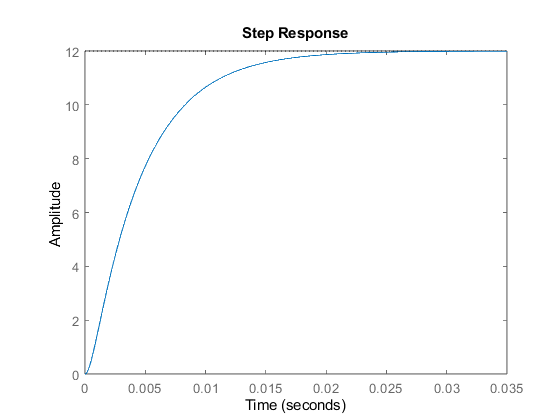

figure
    step(sys_id)

Contrastando la función aproximada con la funcion de transferencia el circuito RLC tenemos 


$$\frac{V_c}{V} = \frac{1}{LCs^2+RCs+1}$$


[N D] = tfdata(sys_id, "v")

N =          0         0   11.9987


D =     0.0000    0.0048    1.0000


L = 0.1; %Definimos un valor para L
C = D(1)/L;
R = D(2)/C;

4 - Una vez determinados los parámetros R, L y C, emplear la serie de corriente desde 0.05seg en adelante para validar el resultado.

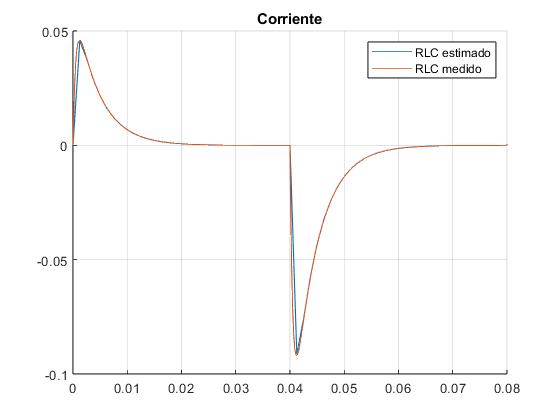

[u,t] = gensig("square",0.08,0.16);
u = -(24*u-12);
A4 = [-R/L -1/L; 1/C 0];
B4 = [1/L; 0];
C4 = [1, 0];
D4 = [0];

% Creamos modelo de espacio de estados
sys_est = ss(A4,B4,C4,D4);

[i_est,t_sim]=lsim(sys_est,u,t);
 
figure('Name','1.4')
hold on
plot(t, i_est)
plot(datos(:,1)-0.01,datos(:,2));grid on; title('Corriente');
legend('RLC estimado','RLC medido')
xlim([0 0.08])

## Caso de estudio N° 2: Sistema de dos variables de estado

Sean las ecuaciones


$$ i_a' = -\frac{R_A}{L_{AA}} i_a-\frac{K_m}{L_{AA}} \omega_r + \frac{1}{L_{AA}} V_A$$



$$\omega_r' = -\frac{B_m}{J} \omega_r+\frac{K_i}{J} i_a-\frac{1}{J} T_L$$



$$\theta_t = \omega_r$$


Implementar un algoritmo de simulación para inferir el comportamiento de las variables interés mediante integración Euler con t=10e-7 segundos para:

1-Obtener el torque máximo que puede soportar el motor modelado mediante las Ecs. cuando se lo alimenta con 12V, graficando para 5 segundos de tiempo la velocidad angular y corriente ia.

Asignamos los valores correspondientes al motor

clear all;
close all;
Laa=366e-6;
J=5e-9;
Ra=55.6;
B=0;
Ki=6.49e-3;
Km=6.53e-3;

delta=10e-07;
ts=5;

Generamos la función de entrada de tensión $V_a$ y $T_L
$ para el motor, a fín de calcular el mayor torque soportado por el mismo. $T_L$ es una función escalón que incrementa el torque de carga a partir de t =2.5s.

Va=12;
t=0:delta:(ts-delta);
T_L = t>=0;
for i=1:ts/delta-delta
    T_L(i)=0;
end

Integramos por euler 

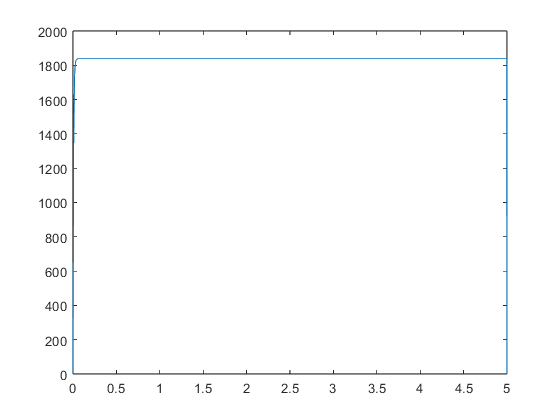

ia = zeros(1,ts/delta);
wr = zeros(1,ts/delta);
o  = zeros(1,ts/delta);

ia(1)=0; wr(1)=0; o(1)=0; %Cond. iniciales
Va=12;
for i=2:(ts/delta-1)
    ia(i)=ia(i-1)+delta*(-Ra*ia(i-1)/Laa-Km*wr(i-1)/Laa+Va/Laa);
    wr(i)=wr(i-1)+delta*(Ki/J*ia(i-1)-B/J*wr(i-1)-T_L(i-1)/J);
    o(i) = o(i-1) + delta*wr(i-1);
end
plot(t, wr)

El torque máximo viene dado por la corriente máxima del motor (en el arranque)

ia_max = max(ia)

ia_max = 0.2147

wr_max = max(wr)

wr_max = 1.8377e+03

T_L_max = Ki*ia_max-B*wr_max

T_L_max = 0.0014

Podemos comprobar que esta es la cifra máxima de torque admitida por el motor si la aplicamos en nuestro modelo.

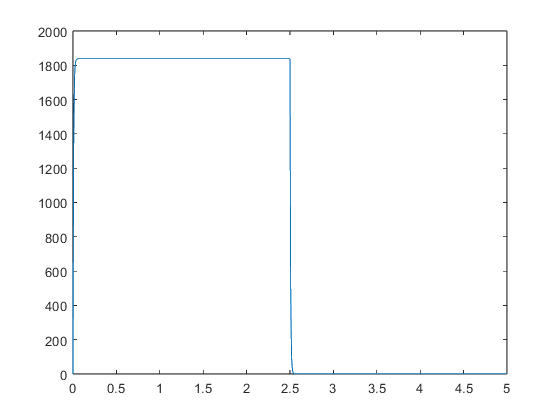

T_L = t>=0;
for i=1:ts/delta/2
    T_L(i)=0;
end
T_L = T_L*0.0014;
ia(1)=0; wr(1)=0; o(1)=0; %Cond. iniciales
Va=12;
for i=2:(ts/delta-1)
    ia(i)=ia(i-1)+delta*(-Ra*ia(i-1)/Laa-Km*wr(i-1)/Laa+Va/Laa);
    wr(i)=wr(i-1)+delta*(Ki/J*ia(i-1)-B/J*wr(i-1)-T_L(i-1)/J);
    o(i) = o(i-1) + delta*wr(i-1);
end
plot(t, wr)

2- Mostrar simulaciones de 5 segundos que permitan observar la corriente $i_a$ en todo  momento y establecer su valor máximo como para dimensionar dispositivos electrónicos.

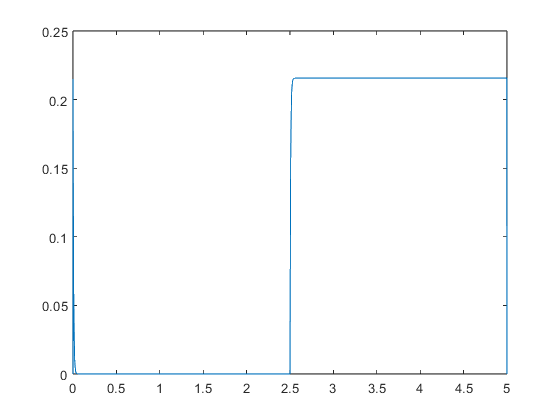

plot(t, ia)

La corriente máxima esta dada por

ia_max = max(ia)

ia_max = 0.2157

3- A partir de las curvas de mediciones de las variables graficadas en la Fig. 1-3, se requiere obtener el modelo del sistema considerando como entrada un escalón de 12V, como salida a la velocidad angular, y a partir de 0,1segundo se aplica un TL aproximado de 7,5 10-2 Nm. En el archivo Curvas_Medidas_Motor.xls están las mediciones, en la primer hoja a los valores y en la segunda los nombres. Se requiere obtener el modelo dinámico, para establecer las constantes de la corriente.

clear all;
%Cargamos los datos medidos
datos = xlsread('Curvas_Medidas_Motor_2023.xlsx');

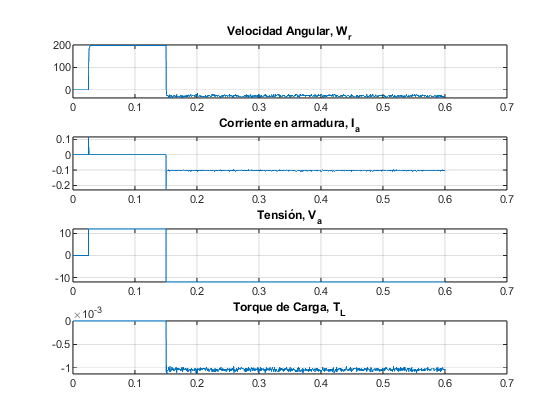

t = datos(:,1);
wr = datos(:,2);
ia = datos(:,3);
Va = datos(:,4);
T_L = datos(:,5);
figure
 subplot(4,1,1);plot(t,wr);grid on; title('Velocidad Angular, W_r');
 subplot(4,1,2);plot(t,ia);grid on; title('Corriente en armadura, I_a');
 subplot(4,1,3);plot(t,Va);grid on; title('Tensión, V_a');
 subplot(4,1,4);plot(t,T_L);grid on; title('Torque, T_L');